close all; clearvars; clc;


if matlab.desktop.editor.isEditorAvailable
    full_path = matlab.desktop.editor.getActiveFilename;
else
    full_path = mfilename('fullpath');
end 
                                            % NOTE:
                                            % A_OK contains the motion data of the 35 participants
[path_script, ~, ~] = fileparts(full_path); % A_OK directory must be in the same dir of this script!

%   Motion Analysis Parameters:
%   Time, Bimanual Dexterity, Distance between instruments, Path lenght,
%   Number of submovements and Speed

## 3D Analysis - Motion analysis parameters (MAPs)

for vc = 1 : 35
    clearvars -except vc matrizR_3D path_script;
    
    MatrizDatos = readmatrix([path_script,'\A_OK\' ,num2str(vc), '.txt']);
    
    Xv=MatrizDatos(:,1);   % In mm
    Yv=MatrizDatos(:,2);
    Zv=MatrizDatos(:,3);
    
    Xa=MatrizDatos(:,4);
    Ya=MatrizDatos(:,5);
    Za=MatrizDatos(:,6);
    
    Fs = 30; % 30 FPS per trial in the stereo system ok
    
    % Symmetrically transfer the point clouds to the first Cartesian quadrant
    desX = min( min(Xv), min(Xa));
    desY = min( min(Yv), min(Ya));
    desZ = min( min(Zv), min(Za));
    
    Xv = Xv - desX;
    Xa = Xa - desX;
    
    Yv = Yv - desY;
    Ya = Ya - desY;
    
    Zv = Zv - desZ;
    Za = Za - desZ;
    %//////////////////////////////////////////////////////////////////////////
    
    
%   Time
            R_time = max(MatrizDatos(:, 7));
        
        
% Path lenght
        %//////////////////////////////////////////////////////////////////////////
        % From mm to meters 1 mm = 0.001 m
        
        Xv = Xv./1000;   
        Yv = Yv./1000;
        Zv = Zv./1000;
        
        Xa = Xa./1000;
        Ya = Ya./1000;
        Za = Za./1000;
        
        
        %//////////////////////////////////////////////////////////////////////////
        %Path Length //////////////////////////////////////////////////////////////
        
            % Right hand                                          % meters
            R_PL_D = sum( sqrt(diff(Xv,1).^2 + diff(Yv,1).^2 + diff(Zv,1).^2));
            
            % Left hand
            R_PL_I = sum( sqrt(diff(Xa,1).^2 + diff(Ya,1).^2 + diff(Za,1).^2));
        
           
            %//////////////////////////////////////////////////////////////////////////
            % Meters to millimeters
            xv = Xv.*1000;
            yv = Yv.*1000;
            zv = Zv.*1000;
            
            xa = Xa.*1000;
            ya = Ya.*1000;
            za = Za.*1000;
            
%Average Speed (mm/s) /////////////////////////////////////////////////////
            
            % Right hand                                             
            SpeedD = sqrt((diff(xv,1)/(1/Fs)).^2 + (diff(yv,1)/(1/Fs)).^2 + (diff(zv,1)/(1/Fs)).^2);
            Mean_SpeedD = mean(SpeedD);
            
            % Left hand
            SpeedI = sqrt((diff(xa,1)/(1/Fs)).^2 + (diff(ya,1)/(1/Fs)).^2 + (diff(za,1)/(1/Fs)).^2);
            Mean_SpeedI = mean(SpeedI);
            
% Bimanual Dexterity
            
            b = zeros(length( SpeedD ),1);
            c = zeros(length( SpeedD ),1);
            d = zeros(length( SpeedD ),1);
            
            for i = 1:length( SpeedD )
                
                b(i) = (SpeedI(i) - Mean_SpeedI) * (SpeedD(i) - Mean_SpeedD);             %
                c(i) = (SpeedI(i) - Mean_SpeedI)^2;
                d(i) = (SpeedD(i) - Mean_SpeedD)^2;
                
            end
            
            R_BD = sum(b) / (sqrt( sum(c) * sum(d) ));  %  Es una correlación
        
        
% Distance between instruments 3D
            
            %Average distance between instruments
            R_AvDisInst = mean( sqrt( (xv-xa).^2 + (yv-ya).^2 + (zv-za).^2));
        
        
% Number of submovements
        
            %Derecha
            R_submD = length(find(SpeedD > 14 ));      % 15 micro 20 lapa es el promedio de todas las Vel
            %Izquierda
            R_submI = length(find(SpeedI > 14 ));
    

% Matrix of Results
        matrizR_3D(vc, :) = [R_time, R_BD, R_AvDisInst, R_PL_D, R_PL_I, R_submD, R_submI, Mean_SpeedD, Mean_SpeedI];
    
end 

matrizR_3D

matrizR_3D =    97.0670    0.6429   11.2103    0.8922    0.8154  560.0000  511.0000    9.1920    8.4007
   92.8670    0.5878    9.9272    0.4914    0.7395  284.0000  516.0000    5.2914    7.9629
   96.5670    0.4708   11.2654    0.6937    0.5815  283.0000  216.0000    7.1832    6.0213
   86.8330    0.7191    9.8777    0.5763    0.5519  386.0000  318.0000    6.6372    6.3553
   87.9670    0.6405   10.2002    0.8858    0.7166  545.0000  432.0000   10.0701    8.1458
  131.2330    0.4020   11.9171    0.8705    1.3242  491.0000  769.0000    6.6334   10.0901
   95.5330    0.7458   10.3045    0.6269    0.7511  336.0000  463.0000    6.5618    7.8623
   85.8000    0.7330   11.0108    0.5994    0.6227  382.0000  385.0000    6.9856    7.2573
   99.7330    0.7947    9.3281    0.5635    0.7166  290.0000  420.0000    5.6504    7.1856
   99.6000    0.3790   10.0743    0.4265    0.4884   87.0000  120.0000    4.2822    4.9041


## 2D Analysis - Motion analysis parameters (MAPs)

for vc = 1 : 35
    clearvars -except vc matrizR_3D matrizR_2D path_script;
    
    MatrizDatos = readmatrix([path_script,'\A_OK\' ,num2str(vc), '.txt']);
    
    Xv=MatrizDatos(:,1);   % In mm
    Yv=MatrizDatos(:,2);
    Zv=MatrizDatos(:,3);
    
    Xa=MatrizDatos(:,4);
    Ya=MatrizDatos(:,5);
    Za=MatrizDatos(:,6);
    
    Fs = 30; % 30 FPS
    
% Symmetrically transfer the point clouds to the first Cartesian quadrant
    desX = min( min(Xv), min(Xa));
    desY = min( min(Yv), min(Ya));
    desZ = min( min(Zv), min(Za));
    
    Xv = Xv - desX;
    Xa = Xa - desX;
    
    Yv = Yv - desY;
    Ya = Ya - desY;
    
    Zv = Zv - desZ;
    Za = Za - desZ;
    %//////////////////////////////////////////////////////////////////////////
    
    
% Time
            R_time = max(MatrizDatos(:, 7));
        
        
% Path lenght
        %//////////////////////////////////////////////////////////////////////////
        % From mm to meters 1 mm = 0.001 m
        
        Xv = Xv./1000;   
        Yv = Yv./1000;
        Zv = Zv./1000;
        
        Xa = Xa./1000;
        Ya = Ya./1000;
        Za = Za./1000;
        

    %Path Length Hands ////////////////////////////////////////////////////////
        
            % Right                                                %Operan en Metros
            R_PL_D = sum( sqrt(diff(Xv,1).^2 + diff(Yv,1).^2 ));
            
            % Left
            R_PL_I = sum( sqrt(diff(Xa,1).^2 + diff(Ya,1).^2 ));
        
        
            %//////////////////////////////////////////////////////////////////////////
            % Meters to millimeters

            xv = Xv.*1000;
            yv = Yv.*1000;
            zv = Zv.*1000;
            
            xa = Xa.*1000;
            ya = Ya.*1000;
            za = Za.*1000;
            
%Average Speed (mm/s) /////////////////////////////////////////////////////
            
            %Derecha                                             %Operan en Milímetros
            SpeedD = sqrt((diff(xv,1)/(1/Fs)).^2 + (diff(yv,1)/(1/Fs)).^2);
            Mean_SpeedD = mean(SpeedD);
            
            %Izquierda
            SpeedI = sqrt((diff(xa,1)/(1/Fs)).^2 + (diff(ya,1)/(1/Fs)).^2);
            Mean_SpeedI = mean(SpeedI);
            
% Bimanual Dexterity
            
            b = zeros(length( SpeedD ),1);
            c = zeros(length( SpeedD ),1);
            d = zeros(length( SpeedD ),1);
            
            for i = 1:length( SpeedD )
                
                b(i) = (SpeedI(i) - Mean_SpeedI) * (SpeedD(i) - Mean_SpeedD);             %
                c(i) = (SpeedI(i) - Mean_SpeedI)^2;
                d(i) = (SpeedD(i) - Mean_SpeedD)^2;
                
            end
            
            R_BD = sum(b) / (sqrt( sum(c) * sum(d) ));  %  Es una correlación
        
        
% Distance between instruments 3D
            
            %Average distance between instruments
            R_AvDisInst = mean( sqrt( (xv-xa).^2 + (yv-ya).^2 ));
        
        
% Number of submovements
        
            %Derecha
            R_submD = length(find(SpeedD > 10 ));      % 15 micro 20 lapa es el promedio de todas las Vel
            %Izquierda
            R_submI = length(find(SpeedI > 10 ));
    

% Matrix of Results

        matrizR_2D(vc, :) = [R_time, R_BD, R_AvDisInst, R_PL_D, R_PL_I, R_submD, R_submI, Mean_SpeedD, Mean_SpeedI];
    
    
end

matrizR_2D

matrizR_2D =    97.0670    0.7325   10.0209    0.5914    0.6081  548.0000  565.0000    6.0931    6.2645
   92.8670    0.7494    8.8863    0.3178    0.4969  260.0000  487.0000    3.4225    5.3511
   96.5670    0.5735    9.8163    0.4338    0.4407  246.0000  300.0000    4.4924    4.5642
   86.8330    0.7232    8.6763    0.3773    0.3457  390.0000  226.0000    4.3456    3.9808
   87.9670    0.7269    9.1635    0.6205    0.5662  485.0000  483.0000    7.0534    6.4361
  131.2330    0.2918   10.9880    0.5515    0.9488  419.0000  693.0000    4.2024    7.2300
   95.5330    0.8235    8.9759    0.4035    0.5032  291.0000  374.0000    4.2233    5.2668
   85.8000    0.8184    9.6684    0.3979    0.4296  329.0000  342.0000    4.6371    5.0066
   99.7330    0.8179    8.3803    0.3948    0.4735  347.0000  369.0000    3.9586    4.7478
   99.6000    0.5429    9.2642    0.2707    0.3378   70.0000  120.0000    2.7182    3.3917


## Statistics. 

Statistically significant differences between the two tracking modalities, 2D vs 3D, in the 6 MAPs

%   Statistical significative differences
%   Experts–trainees (p value)
%   Mann–Whitney U-test, significant differences at the p ≤ 0.05 level are indicated in bold


for n1 =1 : 9
    [Diferences(1,n1), Diferences(2,n1)]   =   ranksum( matrizR_2D(:,n1), matrizR_3D(:,n1));

end

%R_time, R_BD, R_AvDisInst, R_PL_D, R_PL_I, R_submD, R_submI, Mean_SpeedD, Mean_SpeedI

titls = {'Time', 'Bimanual Dexterity', 'Instruments distance', 'Path length R', 'Path length L', 'Submovements R', 'Submovements L', 'Speed R', 'Speed L'};

v_cel = num2cell(Diferences(1,:));

tabl = cell2table(v_cel);

tabl.Properties.VariableNames = titls;

disp(tabl);

    Time    Bimanual Dexterity    Instruments distance    Path length R    Path length L    Submovements R    Submovements L     Speed R       Speed L  
    ____    __________________    ____________________    _____________    _____________    ______________    ______________    __________    __________

     1           0.028905              1.2276e-06          1.6166e-07       1.1178e-05         0.17862           0.48459        1.9555e-07    8.6342e-09



Mann-Whitney U test, the significant differences at the p ≤ 0.05 level

## Cosine similarity


for ci = 1 : 9

    % Comparing the participants' scores in 2D vs 3D for all the 9 MAPs

    senal1 = matrizR_2D(:, ci); % 2D scores
    senal2 = matrizR_3D(:, ci); % 3D scores
    
    % Computing the cosine similarity
    similitud_coseno = dot(senal1, senal2) / (norm(senal1) * norm(senal2));
    
    % Normal signals
    senal1_normalizada = senal1 / norm(senal1);
    senal2_normalizada = senal2 / norm(senal2);
    
    % Similarity between normalized signals
    similitud_normalizada = dot(senal1_normalizada, senal2_normalizada);
    

    simis(1,ci) = similitud_coseno;

    % Para graficar y comparar la tendencia del performance de participantes
    for ni = 1 : 35
    
        normG2D(ci, ni) = (matrizR_2D(ni, ci) / norm(matrizR_2D(:, ci)));

        normG3D(ci, ni) = (matrizR_3D(ni, ci) / norm(matrizR_3D(:, ci)));
    
    end

end

v_cel = num2cell(simis);

tabl = cell2table(v_cel);

tabl.Properties.VariableNames = titls;


Cosine similarity (2D vs 3D). Where 1 means the greatest similarity between the signals.

disp(tabl);

    Time    Bimanual Dexterity    Instruments distance    Path length R    Path length L    Submovements R    Submovements L    Speed R    Speed L
    ____    __________________    ____________________    _____________    _____________    ______________    ______________    _______    _______

     1           0.99478                0.99973              0.99894          0.99792          0.99617           0.99244        0.99881    0.99762



## Ploting the similarities

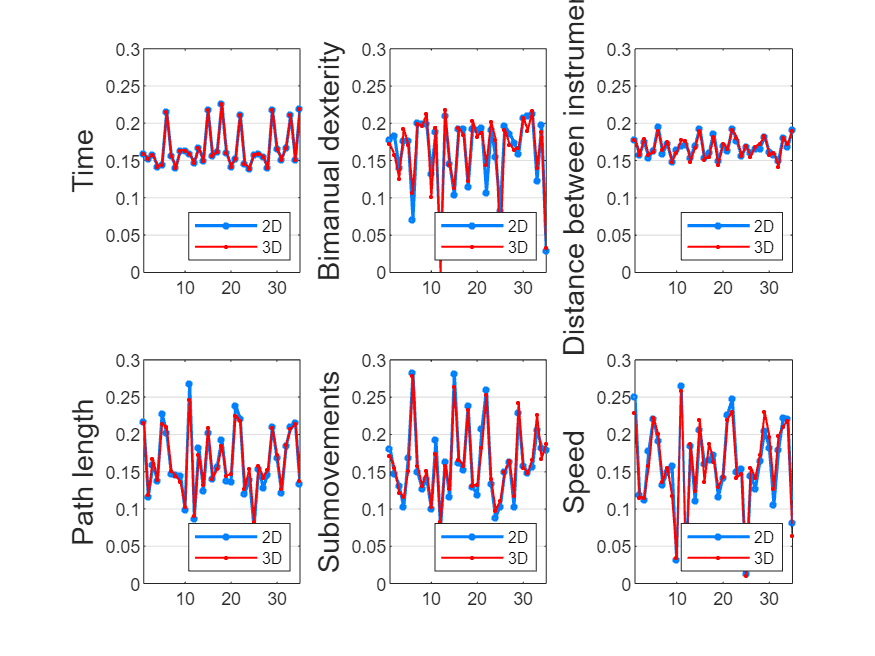


markerSize = 2;

figure

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%    1

    subplot(2,3,1)
    plot(normG2D(1, :), 'b-', 'LineWidth', 1.5, 'DisplayName', '2D', 'Marker', 'o', 'MarkerSize', markerSize)
    
    xlim([1 35])
    ylim([0 0.3])
    grid on
    
    set(gca, 'YGrid', 'on');
    set(gca, 'XGrid', 'off');
    legend('Location','southeast');
    ylabel('Time', 'FontSize', 14)
    
    h = findobj(gca, 'Type', 'line');
    set(h, 'Color', [0.0 0.5 1 0.9]);  % 50% transparency on blue
    
    hold on
    j = plot(normG3D(1, :), 'r-', 'LineWidth', 1, 'DisplayName', '3D', 'Marker', '*', 'MarkerSize', markerSize);
    set(j, 'Color', [1 0.0 0.0 0.90]);  

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%    2

    subplot(2,3,2)
    plot(normG2D(2, :), 'b-', 'LineWidth', 1.5, 'DisplayName', '2D', 'Marker', 'o', 'MarkerSize', markerSize)
    xlim([1 35])
    ylim([0 0.3])
    grid on
    
    set(gca, 'YGrid', 'on');
    set(gca, 'XGrid', 'off');
    legend('Location','southeast');
    ylabel('Bimanual dexterity', 'FontSize', 14)
    
    h = findobj(gca, 'Type', 'line');
    set(h, 'Color', [0.0 0.5 1 0.9]);  
    
    hold on
    j = plot(normG3D(2, :), 'r-', 'LineWidth', 1, 'DisplayName', '3D', 'Marker', '*', 'MarkerSize', markerSize);
    set(j, 'Color', [1 0.0 0.0 0.90]);  


    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%    3

    subplot(2,3,3)
    plot(normG2D(3, :), 'b-', 'LineWidth', 1.5, 'DisplayName', '2D', 'Marker', 'o', 'MarkerSize', markerSize)
    xlim([1 35])
    ylim([0 0.3])
    grid on
    
    set(gca, 'YGrid', 'on');
    set(gca, 'XGrid', 'off');
    legend('Location','southeast');
    ylabel('Distance between instruments', 'FontSize', 14)
    
    h = findobj(gca, 'Type', 'line');
    set(h, 'Color', [0.0 0.5 1 0.9]);  
    
    hold on
    j = plot(normG3D(3, :), 'r-', 'LineWidth', 1, 'DisplayName', '3D', 'Marker', '*', 'MarkerSize', markerSize);
    set(j, 'Color', [1 0.0 0.0 0.90]);  


    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%    4

    subplot(2,3,4)
    plot(normG2D(4, :), 'b-', 'LineWidth', 1.5, 'DisplayName', '2D', 'Marker', 'o', 'MarkerSize', markerSize)
    xlim([1 35])
    ylim([0 0.3])
    grid on
    
    set(gca, 'YGrid', 'on');
    set(gca, 'XGrid', 'off');
    legend('Location','southeast');
    ylabel('Path length', 'FontSize', 14)
    
    h = findobj(gca, 'Type', 'line');
    set(h, 'Color', [0.0 0.5 1 0.9]);  
    
    hold on
    j = plot(normG3D(4, :), 'r-', 'LineWidth', 1, 'DisplayName', '3D', 'Marker', '*', 'MarkerSize', markerSize);
    set(j, 'Color', [1 0.0 0.0 0.90]);  


    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%    5

    subplot(2,3,5)
    plot(normG2D(5, :), 'b-', 'LineWidth', 1.5, 'DisplayName', '2D', 'Marker', 'o', 'MarkerSize', markerSize)
    xlim([1 35])
    ylim([0 0.3])
    grid on
    
    set(gca, 'YGrid', 'on');
    set(gca, 'XGrid', 'off');
    legend('Location','southeast');
    ylabel('Submovements', 'FontSize', 14)
    
    h = findobj(gca, 'Type', 'line');
    set(h, 'Color', [0.0 0.5 1 0.9]);  
    
    hold on
    j = plot(normG3D(5, :), 'r-', 'LineWidth', 1, 'DisplayName', '3D', 'Marker', '*', 'MarkerSize', markerSize);
    set(j, 'Color', [1 0.0 0.0 0.90]); 


    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%    6

    subplot(2,3,6)
    plot(normG2D(6, :), 'b-', 'LineWidth', 1.5, 'DisplayName', '2D', 'Marker', 'o', 'MarkerSize', markerSize)
    xlim([1 35])
    ylim([0 0.3])
    grid on
    
    set(gca, 'YGrid', 'on');
    set(gca, 'XGrid', 'off');
    legend('Location','southeast');
    ylabel('Speed', 'FontSize', 14)
    
    h = findobj(gca, 'Type', 'line');
    set(h, 'Color', [0.0 0.5 1 0.9]);  
    
    hold on
    j = plot(normG3D(6, :), 'r-', 'LineWidth', 1, 'DisplayName', '3D', 'Marker', '*', 'MarkerSize', markerSize);
    set(j, 'Color', [1 0.0 0.0 0.90]);  